# Calculate daily generation of NYAM units

## Import the data

### Import the RGGI generation data

clear;
% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
generationDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(generationDataStore);

### Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("D:\EERL\ny_academic_model\data\EPA_AMPD\RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType", "NamePlateRatingMW", "GrossLoadMWh"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Exclude generators with zero gross load in 2019
generatorCombiner = generatorCombiner(generatorCombiner.GrossLoadMWh > 0, :);
% Remove unused categories
generatorCombiner.NYISOname = removecats(generatorCombiner.NYISOname);
generatorCombiner.PTID = removecats(generatorCombiner.PTID);
generatorCombiner.FacilityName = removecats(generatorCombiner.FacilityName);
generatorCombiner.FacilityID = removecats(generatorCombiner.FacilityID);
generatorCombiner.UnitID = removecats(generatorCombiner.UnitID);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);
generatorCombiner.Region = removecats(generatorCombiner.Region);
generatorCombiner.UnitType = removecats(generatorCombiner.UnitType);
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);

### Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
jointGenAll = outerjoin(genAll,generatorCombiner,'Type', 'right', 'Keys',{'FacilityName','FacilityID','UnitID'},...
    "LeftVariables", {'Date', 'Hour', 'GrossLoadMW', 'OperatingTime', 'HeatInputMMBtu'}, "RightVariables", ...
    {'NYISOname', 'PTID', 'FacilityName', 'FacilityID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'NamePlateRatingMW'});

## Calculate daily power generation of each NYAM units

### Subset generation total time series dataset by NYAM units

genA2FCC = jointGenAll(jointGenAll.NYAMUnit == "A2F-CC", :);
genA2FST = jointGenAll(jointGenAll.NYAMUnit == "A2F-ST", :);
genGHIST = jointGenAll(jointGenAll.NYAMUnit == "GHI-ST", :);
genJCC = jointGenAll(jointGenAll.NYAMUnit == "J-CC", :);
genJCT = jointGenAll(jointGenAll.NYAMUnit == "J-CT", :);
genJST = jointGenAll(jointGenAll.NYAMUnit == "J-ST", :);
genKCT = jointGenAll(jointGenAll.NYAMUnit == "K-CT", :);
genKST = jointGenAll(jointGenAll.NYAMUnit == "K-ST", :);

### Calculate hourly power generation

genHourlyA2FCC = groupsummary(genA2FCC, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyA2FST = groupsummary(genA2FST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyGHIST = groupsummary(genGHIST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyJCC = groupsummary(genJCC, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyJCT = groupsummary(genJCT, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyJST = groupsummary(genJST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyKCT = groupsummary(genKCT, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
genHourlyKST = groupsummary(genKST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);

### Write hourly generation and heat input rate of NYAM units into a file

genHourlyAll = table(genHourlyA2FCC.Date, genHourlyA2FCC.Hour, genHourlyA2FCC.sum_GrossLoadMW, ...
    genHourlyA2FST.sum_GrossLoadMW, genHourlyGHIST.sum_GrossLoadMW, genHourlyJCC.sum_GrossLoadMW, ...
    genHourlyJCT.sum_GrossLoadMW, genHourlyJST.sum_GrossLoadMW, genHourlyKCT.sum_GrossLoadMW, ...
    genHourlyKST.sum_GrossLoadMW, 'VariableNames', ["Date", "Hour", "A2FCC", "A2FST", ...
    "GHIST", "JCC", "JCT", "JST", "KCT", "KST"]);
heatHourlyAll = table(genHourlyA2FCC.Date, genHourlyA2FCC.Hour, genHourlyA2FCC.sum_HeatInputMMBtu, ...
    genHourlyA2FST.sum_HeatInputMMBtu, genHourlyGHIST.sum_HeatInputMMBtu, genHourlyJCC.sum_HeatInputMMBtu, ...
    genHourlyJCT.sum_HeatInputMMBtu, genHourlyJST.sum_HeatInputMMBtu, genHourlyKCT.sum_HeatInputMMBtu, ...
    genHourlyKST.sum_HeatInputMMBtu, 'VariableNames', ["Date", "Hour", "A2FCC", "A2FST", ...
    "GHIST", "JCC", "JCT", "JST", "KCT", "KST"]);

writetable(genHourlyAll, 'D:\EERL\ny_academic_model\data\data_analysis\genHourlyAll2019.csv', "Delimiter", ',');
writetable(heatHourlyAll, 'D:\EERL\ny_academic_model\data\data_analysis\HIRHourlyAll2019.csv', "Delimiter", ',');

## Clean the data

% Create a cell array to store gen-heat tables
NYAMUnitNames = ["A2F-CC", "A2F-ST", "GHI-ST", "J-CC", "J-CT", "J-ST", "K-CT", "K-ST"];
genHeatTables = {genHourlyA2FCC, genHourlyA2FST, genHourlyGHIST, genHourlyJCC, genHourlyJCT, genHourlyJST, genHourlyKCT, genHourlyKST};

% Remove useless variables and change varaible names
for i=1:8
    genHeatTables{i} = removevars(genHeatTables{i}, "GroupCount");
    genHeatTables{i}.Properties.VariableNames = ["Date", "Hour", "GrossLoad", "HeatInput"];
    % Remove zero generation
    genHeatTables{i} = genHeatTables{i}(genHeatTables{i}.GrossLoad > 0, :);
end

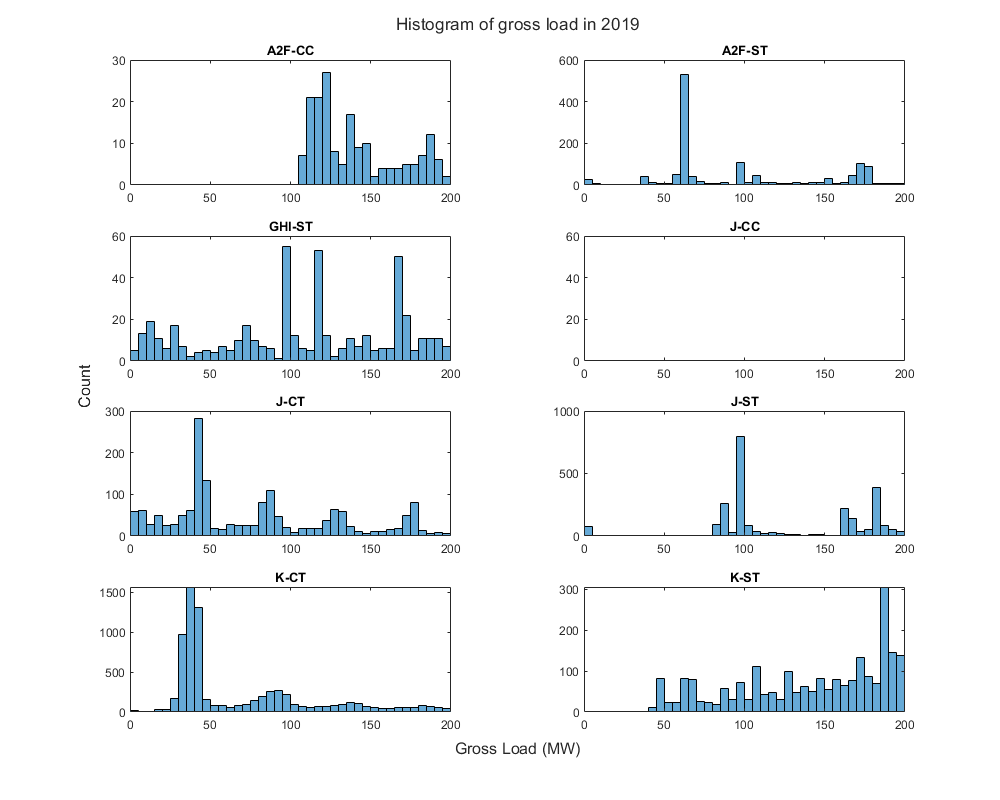

t = tiledlayout(4,2);
for i=1:8
    nexttile;
    h = histogram(genHeatTables{i}.GrossLoad);
    h.BinWidth = 5;
    title(NYAMUnitNames(i));
    xlim([0, 200]);
    box on;
end
title(t, "Histogram of gross load in 2019");
xlabel(t, "Gross Load (MW)");
ylabel(t, "Count");
set(gcf, 'Position', [50, 50, 1000, 800]);

### Visualize the original data

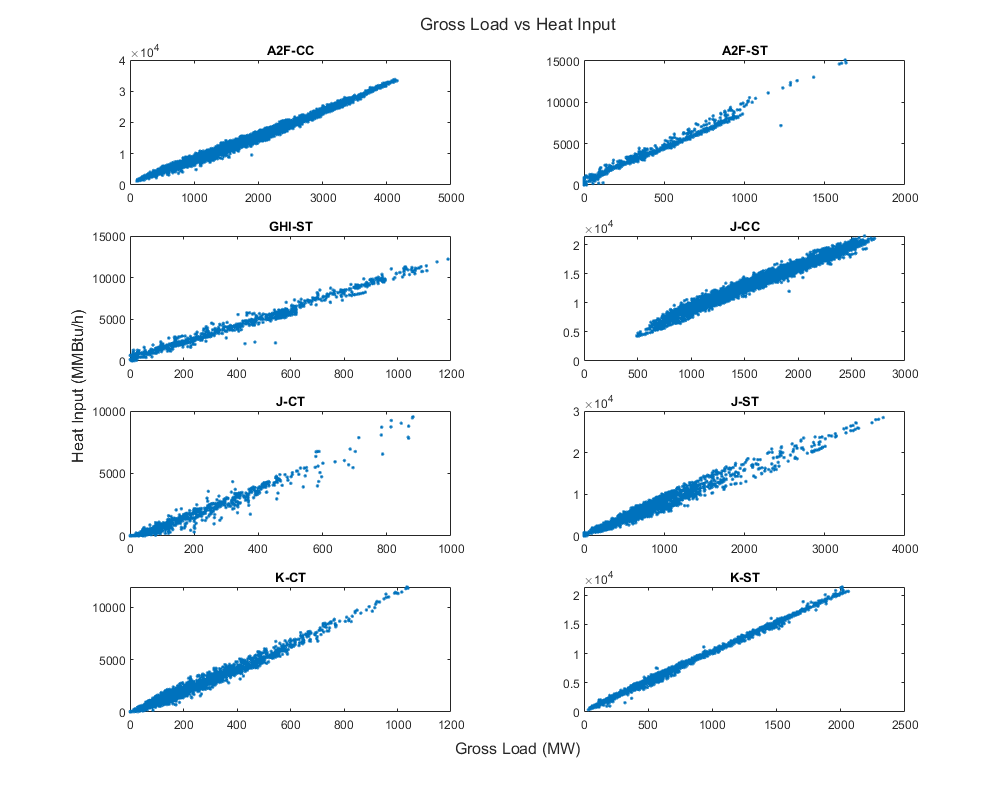

t = tiledlayout(4,2);
for i=1:8
    nexttile;
    scatter(genHeatTables{i}.GrossLoad, genHeatTables{i}.HeatInput, '.');
    title(NYAMUnitNames(i));
    box on;
end
title(t, "Gross Load vs Heat Input");
xlabel(t, "Gross Load (MW)");
ylabel(t, "Heat Input (MMBtu/h)");

set(gcf, 'Position', [50, 50, 1000, 800]);

### Remove outliers in heat input data

cleanedGenHeatTables = cell(1,8);
for i=1:8
    heatStats = groupsummary(genHeatTables{i}, "GrossLoad", "median", "HeatInput");
    [cleanedMedian,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(heatStats.median_HeatInput, ...
        'linear','movmedian',200,'SamplePoints',heatStats.GrossLoad);
    heatStats.cleanedMedian_HeatInput = cleanedMedian;
    genHeat = innerjoin(heatStats, genHeatTables{i},"Keys", "GrossLoad", "LeftVariables", ...
        ["GrossLoad", "median_HeatInput", "cleanedMedian_HeatInput"], "RightVariables", ["HeatInput", "Date", "Hour"]);
    
    heatDeviation = genHeat.HeatInput - genHeat.cleanedMedian_HeatInput;    
    lowPercent = 5;
    highPercent = 95;
    [hOut,hLow,hHigh,~] = isoutlier(heatDeviation,"percentiles", [lowPercent, highPercent]); 
    cleanedGenHeatTables{i} = genHeat(~hOut, :);
end

### Visualize the cleaned data

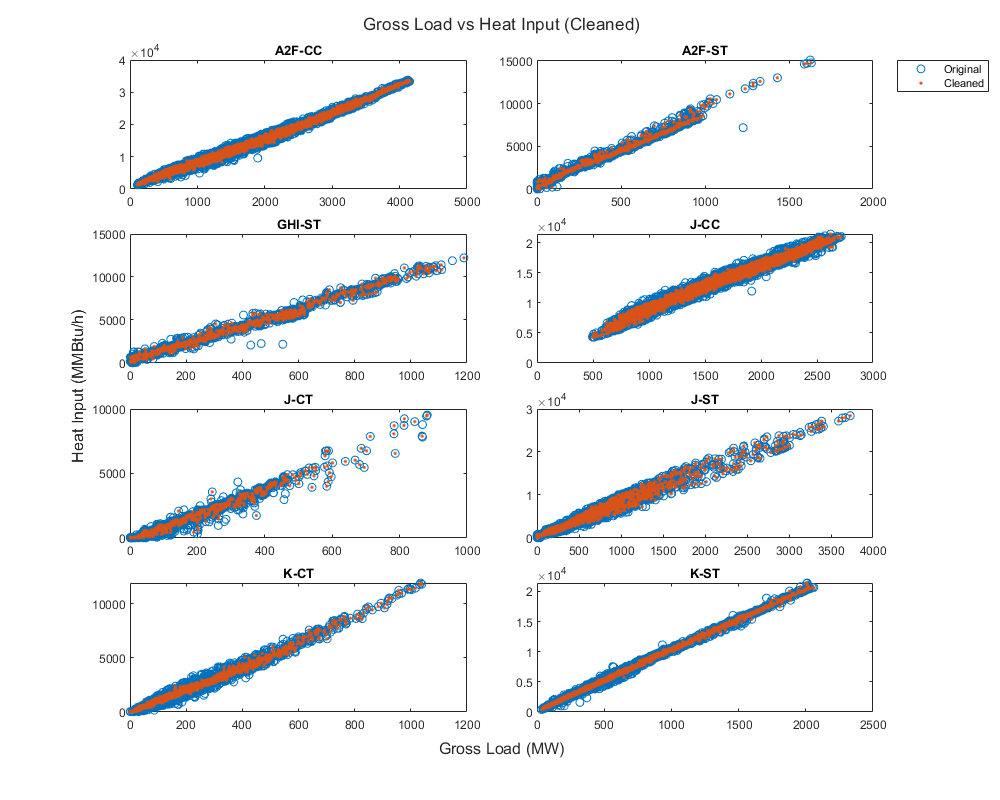

t = tiledlayout(4,2,"TileSpacing","compact");
for i=1:8
    nexttile;
    s1 = scatter(genHeatTables{i}.GrossLoad, genHeatTables{i}.HeatInput,'o');
    hold on;
    s2 = scatter(cleanedGenHeatTables{i}.GrossLoad, cleanedGenHeatTables{i}.HeatInput, '.');
    hold off; box on;
    title(NYAMUnitNames(i));
    if i == 2
        lgd = legend([s1, s2], ["Original", "Cleaned"]);
        set(lgd, "Location", "bestoutside");
    end
end
title(t, "Gross Load vs Heat Input (Cleaned)");
xlabel(t, "Gross Load (MW)");
ylabel(t, "Heat Input (MMBtu/h)");

set(gcf, 'Position', [50, 50, 1000, 800]);

## Fit polynomial relation of gross load and heat input

### Fit quadratic relations

polyGenHeat = zeros(8, 3);
for i=1:8
    table = cleanedGenHeatTables{i};
    p = polyfit(table.GrossLoad, table.HeatInput, 2);
    y_fit = polyval(p, table.GrossLoad);
    cleanedGenHeatTables{i}.poly_HeatInput = y_fit;
    polyGenHeat(i, :) = p;
end

### Fit linear relation of gross load and heat input

lmGenHeat = zeros(8, 2);
for i=1:8
    table = cleanedGenHeatTables{i};
    lm = fitlm(table.GrossLoad, table.HeatInput);
    y_fit = feval(lm, table.GrossLoad);
    cleanedGenHeatTables{i}.lm_HeatInput = y_fit;
    lmGenHeat(i, :) = table2array(lm.Coefficients(:,1))';
end

### Visualize quadratic and linear relations

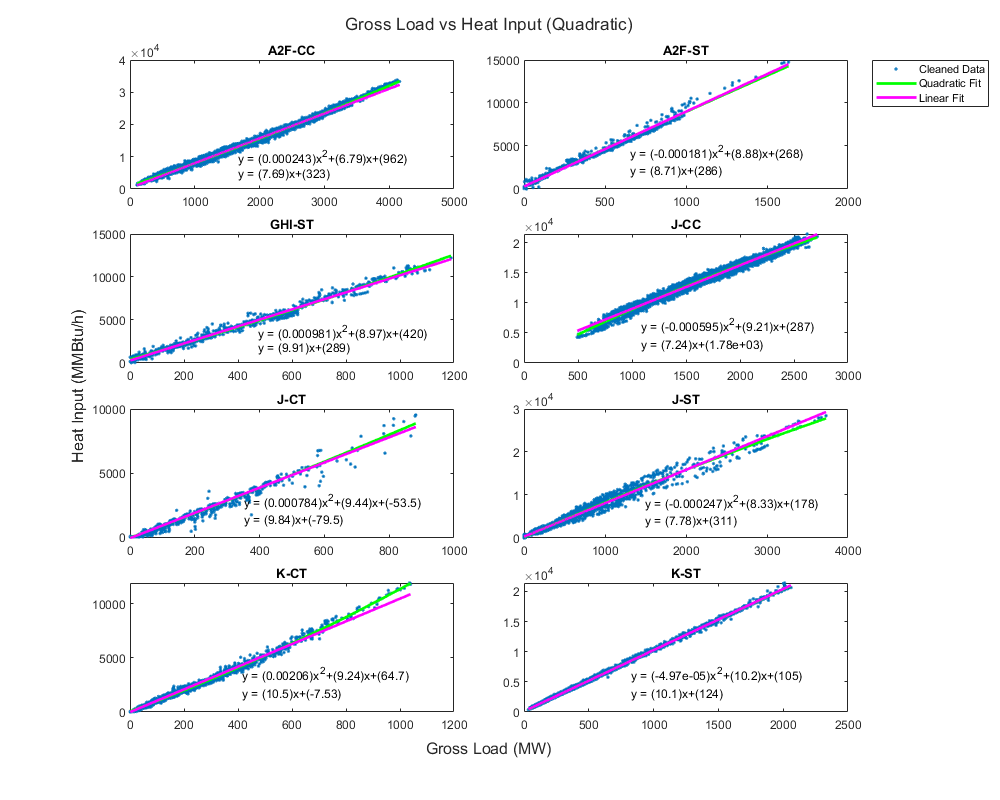

t = tiledlayout(4,2, "TileSpacing","compact");
for i=1:8
    nexttile;
    table = cleanedGenHeatTables{i};
    sc1 = scatter(table.GrossLoad, table.HeatInput, '.');
    hold on;
    p1 = plot(table.GrossLoad, table.poly_HeatInput, 'g-', 'Linewidth', 2);
    p2 = plot(table.GrossLoad, table.lm_HeatInput, 'm-', "LineWidth", 2);
    hold off; box on;
    title(NYAMUnitNames(i));
    s1 = sprintf('y = (%.3g)x^2+(%.3g)x+(%.3g)',polyGenHeat(i,1), polyGenHeat(i,2), polyGenHeat(i,3));
    sx1 = 0.4*max(table.GrossLoad);
    sy1 = 0.3*max(table.HeatInput);
    text(sx1, sy1, s1, "FontSize", 9);
    s2 = sprintf('y = (%.3g)x+(%.3g)',lmGenHeat(i,2), lmGenHeat(i,1));
    sx2 = 0.4*max(table.GrossLoad);
    sy2 = 0.15*max(table.HeatInput);
    text(sx2, sy2, s2, "FontSize", 9);
    if i == 2
        lgd = legend(["Cleaned Data","Quadratic Fit","Linear Fit"]);
        set(lgd, "Location", "bestoutside");
    end
end
title(t, "Gross Load vs Heat Input (Quadratic)");
xlabel(t, "Gross Load (MW)");
ylabel(t, "Heat Input (MMBtu/h)");

set(gcf, 'Position', [50, 50, 1000, 800]);

## Cost of power generation

### Define cost parameters

% Fuel cost from EIA 2018 Electric Power Anual
% Price data in NY ($/MMBtu)
CoalPrice = 2.15;
FOPrice = 13.16;
NGPrice = 3.76;
CCOMCost = 2.37+2.71

CCOMCost =          5.08


CTOMCost = 2.37+2.71

CTOMCost =          5.08


STOMCost = 5.19+5.27

STOMCost =         10.46


% Operation cost from EIA Annual Energy Outlook 2020
% National price data ($/MWh) total levelized cost of electricity (LCOE)
% estimation in 2022 including tax credit
% CCOMCost = 33.53;
% CTOMCost = 64.19;
% STOMCost = 33.86;

### Calculate fuel and O&M cost for each unit

UnitTotCap = groupsummary(generatorCombiner, "NYAMUnit", "sum", ["GrossLoadMWh", "NamePlateRatingMW"]);
UnitFuelTotCap = groupsummary(generatorCombiner, ["NYAMUnit", "UnitType", "FuelType"], "sum", ["GrossLoadMWh", "NamePlateRatingMW"]);
jointUnitFuelTotCap = outerjoin(UnitFuelTotCap,UnitTotCap,'Keys',{'NYAMUnit'},'MergeKeys',true, ...
    "LeftVariables",["NYAMUnit","UnitType","FuelType","sum_GrossLoadMWh","sum_NamePlateRatingMW"],"RightVariables",["sum_GrossLoadMWh","sum_NamePlateRatingMW"]);
jointUnitFuelTotCap.Properties.VariableNames = ["NYAMUnit", "UnitType", "FuelType", "SubtotalLoadByFuel", "SubtotalCapacityByFuel", "TotalLoad", "TotalCapacity"];
jointUnitFuelTotCap.FuelLoadFrac = jointUnitFuelTotCap.SubtotalLoadByFuel./jointUnitFuelTotCap.TotalLoad;
jointUnitFuelTotCap.FuelCapFrac = jointUnitFuelTotCap.SubtotalCapacityByFuel./jointUnitFuelTotCap.TotalCapacity;

jointUnitFuelTotCap.FuelPrice(jointUnitFuelTotCap.FuelType == "Coal") = CoalPrice;
jointUnitFuelTotCap.FuelPrice(jointUnitFuelTotCap.FuelType == "Fuel oil") = FOPrice;
jointUnitFuelTotCap.FuelPrice(jointUnitFuelTotCap.FuelType == "Natural gas") = NGPrice;
jointUnitFuelTotCap.OMPrice(jointUnitFuelTotCap.UnitType == "Combined cycle") = CCOMCost;
jointUnitFuelTotCap.OMPrice(jointUnitFuelTotCap.UnitType == "Combustion turbine") = CTOMCost;
jointUnitFuelTotCap.OMPrice(jointUnitFuelTotCap.UnitType == "Steam turbine") = STOMCost;
jointUnitFuelTotCap.CapWeightedFuelPrice = jointUnitFuelTotCap.FuelCapFrac.*jointUnitFuelTotCap.FuelPrice;
jointUnitFuelTotCap.CapWeightedOMPrice = jointUnitFuelTotCap.FuelCapFrac.*jointUnitFuelTotCap.OMPrice;
jointUnitFuelTotCap.LoadWeightedFuelPrice = jointUnitFuelTotCap.FuelLoadFrac.*jointUnitFuelTotCap.FuelPrice;
jointUnitFuelTotCap.LoadWeightedOMPrice = jointUnitFuelTotCap.FuelLoadFrac.*jointUnitFuelTotCap.OMPrice;

UnitPrice = groupsummary(jointUnitFuelTotCap, "NYAMUnit", "sum", ["CapWeightedFuelPrice", "CapWeightedOMPrice", "LoadWeightedFuelPrice", "LoadWeightedOMPrice"]);
UnitPrice = removevars(UnitPrice, "GroupCount");
UnitPrice.Properties.VariableNames = ["NYAMUnit", "CapWtFuelPrice", "CapWtOMPrice", "LdWtFuelPrice", "LdWtOMPrice"]

UnitPrice = 8×5 table
    NYAMUnit    CapWtFuelPrice    CapWtOMPrice    LdWtFuelPrice    LdWtOMPrice
    ________    ______________    ____________    _____________    ___________

     A2F-CC           3.76            5.08             3.76            5.08   
     A2F-ST         9.4996           10.46           3.0712           10.46   
     GHI-ST          7.631           10.46            6.885           10.46   
     J-CC             3.76            5.08             3.76            5.08   
     J-CT             3.76            5.08             3.76            5.08   
     J-ST           10.851           10.46           10.354           10.46   
     K-CT           7.0062            5.08           4.2157            5.08   
     K-ST           5.2967           10.46           4.4842           10.46   


### Find the price function

polyGenPrice = polyGenHeat.*UnitPrice.LdWtFuelPrice % Fuel price in $/MW

polyGenPrice =    0.00091366       25.533       3615.4
  -0.00055695       27.272       823.57
    0.0067569       61.791       2891.8
   -0.0022354       34.632       1080.4
    0.0029487       35.481      -201.31
   -0.0025554       86.257       1840.3
    0.0086793        38.96       272.55
  -0.00022303       45.823       470.74


polyGenPrice(:,2) = polyGenPrice(:,2) + UnitPrice.LdWtOMPrice % Total price in $/MW

polyGenPrice =    0.00091366       30.613       3615.4
  -0.00055695       37.732       823.57
    0.0067569       72.251       2891.8
   -0.0022354       39.712       1080.4
    0.0029487       40.561      -201.31
   -0.0025554       96.717       1840.3
    0.0086793        44.04       272.55
  -0.00022303       56.283       470.74


lmGenPrice = lmGenHeat.*UnitPrice.LdWtFuelPrice % Linear fuel price in $/MW

lmGenPrice =        1216.4       28.913
        879.2       26.762
       1989.6       68.215
       6704.6       27.207
       -298.8       36.994
       3217.5       80.527
      -31.737        44.21
       554.62       45.459


lmGenPrice(:, 2) = lmGenPrice(:, 2) + UnitPrice.LdWtOMPrice % Linear total price in $/MW

lmGenPrice =        1216.4       33.993
        879.2       37.222
       1989.6       78.675
       6704.6       32.287
       -298.8       42.074
       3217.5       90.987
      -31.737        49.29
       554.62       55.919


% Reference price curve from Steve's model
polyGenPriceSteve = [0.001, 9.5, 400;
                    0.001, 9, 300;
                    0.001, 7.5, 250;
                    0.001, 10, 350;
                    0.001, 13, 50;
                    0.001, 9, 175;
                    0.001, 13.2, 50;
                    0.001, 8, 225]

polyGenPriceSteve =         0.001          9.5          400
        0.001            9          300
        0.001          7.5          250
        0.001           10          350
        0.001           13           50
        0.001            9          175
        0.001         13.2           50
        0.001            8          225


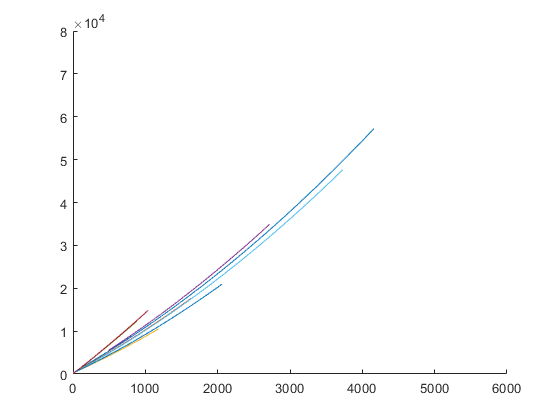

figure;
hold on;
for i=1:8
    load = cleanedGenHeatTables{i}.GrossLoad;    
    tot_cost = polyval(polyGenPriceSteve(i, :), load);
    plot(load, tot_cost);
end
hold off;
axis([0, 6000, 0, 80000]);

polyGenPriceSteveTot = [polyGenPriceSteve, zeros(8, 1)]

polyGenPriceSteveTot =         0.001          9.5          400            0
        0.001            9          300            0
        0.001          7.5          250            0
        0.001           10          350            0
        0.001           13           50            0
        0.001            9          175            0
        0.001         13.2           50            0
        0.001            8          225            0


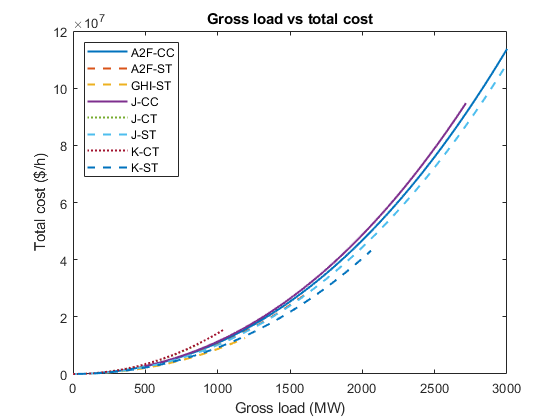

figure;
hold on;
for i=1:8
    load = cleanedGenHeatTables{i}.GrossLoad;    
    tot_cost = polyval(polyGenPriceSteveTot(i, :), load);
    if (i==1)||(i==4)
        lineStype = '-';
    elseif (i==2)||(i==3)||(i==6)||(i==8)
        lineStype = '--';
    else
        lineStype = ':';
    end
    plot(load, tot_cost, 'LineStyle', lineStype, 'LineWidth', 1.5);
end
hold off; box on;
title("Gross load vs total cost");
xlabel("Gross load (MW)");
ylabel("Total cost ($/h)");
axis([0, 3000, 0, 1.2e8]);
legend(NYAMUnitNames, 'Location', 'northwest');

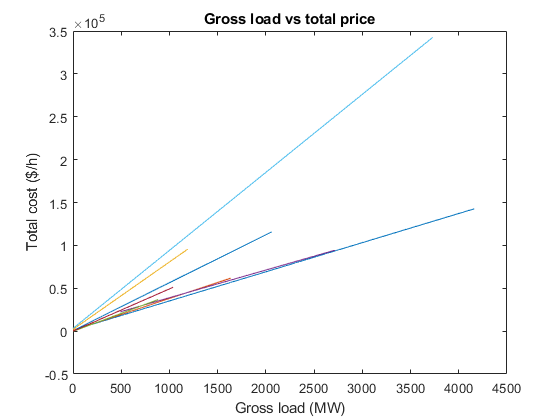

figure;
hold on;
for i=1:8
    table = cleanedGenHeatTables{i};    
    table.PriceLinear = lmGenPrice(i,1) + lmGenPrice(i,2)*table.GrossLoad;
    plot(table.GrossLoad, table.PriceLinear);
end
hold off; box on;
title("Gross load vs total price");
xlabel("Gross load (MW)");
ylabel("Total cost ($/h)");

% axis([0, 4000, 0, 2e8]);

### Visualize price curve

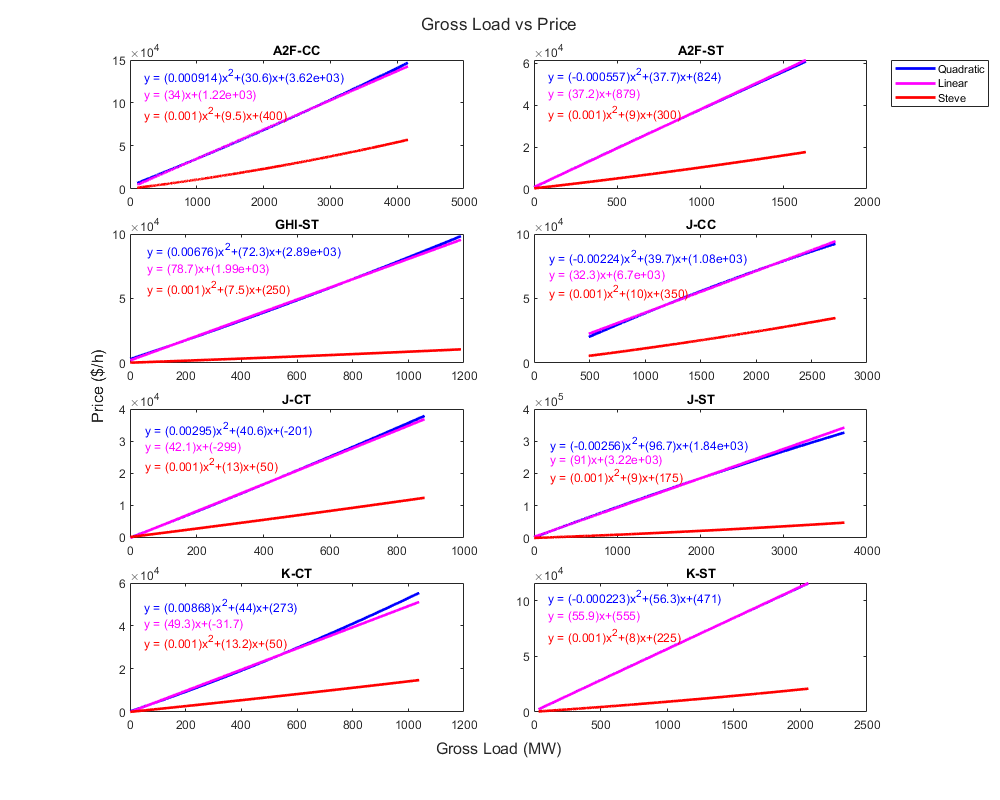

t = tiledlayout(4,2, "TileSpacing","compact");
for i=1:8
    table = cleanedGenHeatTables{i};
    table.PricePoly = polyval(polyGenPrice(i, :), table.GrossLoad);
    nexttile;
    p1 = plot(table.GrossLoad, table.PricePoly, 'b-','LineWidth',2);
    hold on;
    table.PriceLinear = lmGenPrice(i,1) + lmGenPrice(i,2)*table.GrossLoad;
    p2 = plot(table.GrossLoad, table.PriceLinear, 'm-','LineWidth',2);
    table.PriceSteve = polyval(polyGenPriceSteve(i, :), table.GrossLoad);
    p3 = plot(table.GrossLoad, table.PriceSteve, 'r-','LineWidth',2);
    title(NYAMUnitNames(i));
    s1 = sprintf('y = (%.3g)x^2+(%.3g)x+(%.3g)',polyGenPrice(i,1), polyGenPrice(i,2), polyGenPrice(i,3));
    sx1 = 0.05*max(table.GrossLoad);
    sy1 = 0.9*max(table.PricePoly);
    text(sx1, sy1, s1, "FontSize", 9, "Color",'b');
    s2 = sprintf('y = (%.3g)x+(%.3g)',lmGenPrice(i,2), lmGenPrice(i,1));
    sx2 = 0.05*max(table.GrossLoad);
    sy2 = 0.75*max(table.PricePoly);
    text(sx2, sy2, s2, "FontSize", 9,"color", 'm');
    s3 = sprintf('y = (%.3g)x^2+(%.3g)x+(%.3g)',polyGenPriceSteve(i,1), polyGenPriceSteve(i,2), polyGenPriceSteve(i,3));
    sx3 = 0.05*max(table.GrossLoad);
    sy3 = 0.6*max(table.PricePoly);
    text(sx3, sy3, s3, "FontSize", 9, "Color",'r');
    hold off; box on;
    if i == 2
        lgd = legend([p1, p2, p3], ["Quadratic", "Linear", "Steve"]);
        set(lgd, "Location", "bestoutside");
    end
end
title(t, "Gross Load vs Price");
xlabel(t, "Gross Load (MW)");
ylabel(t, "Price ($/h)");
set(gcf, 'Position', [50, 50, 1000, 800]);

## Generation for specific dates for NYAM modeling

date1 = 'Jan-19-2016';
date2 = 'Mar-22-2016';
date3 = 'Jul-25-2016';
date4 = 'Nov-10-2016';
genAllDate1 = genHourlyAll(genHourlyAll.Date == '01/15/2019', :);
genAllDate2 = genHourlyAll(genHourlyAll.Date == '03/22/2019', :);
genAllDate3 = genHourlyAll(genHourlyAll.Date == '07/25/2019', :);
genAllDate4 = genHourlyAll(genHourlyAll.Date == '11/10/2019', :);
genAllDates = {genAllDate1, genAllDate2, genAllDate3, genAllDate4};
dates = [date1; date2; date3; date4];

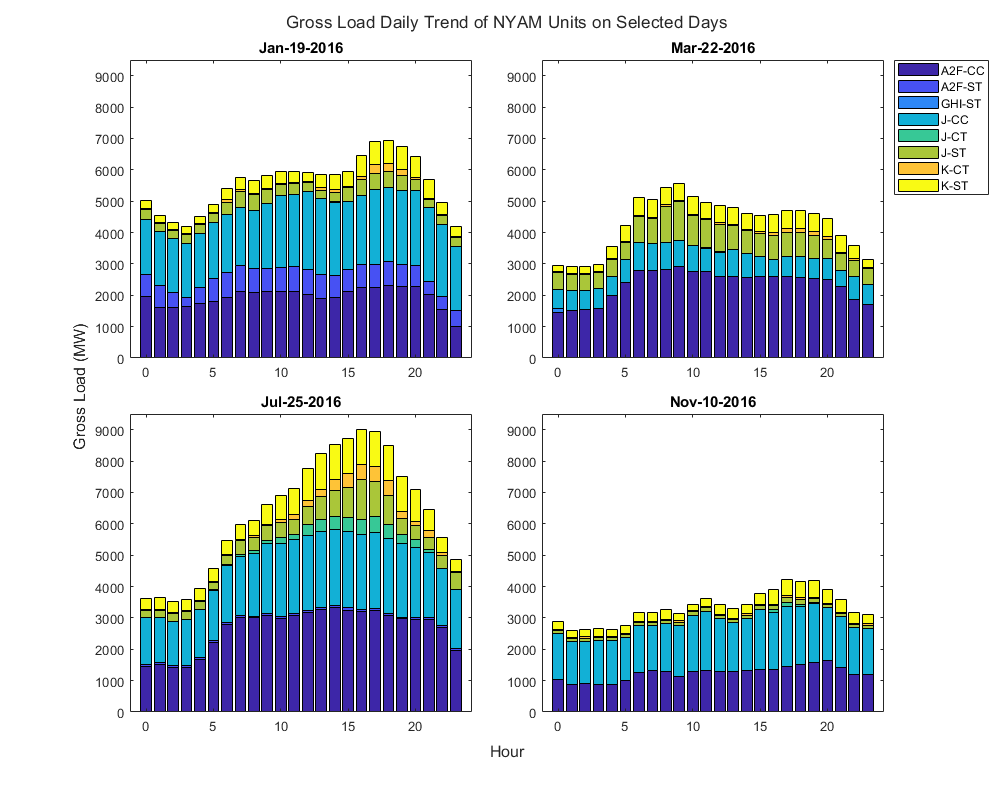

t = tiledlayout(2,2, "TileSpacing","compact");
for i=1:4
    nexttile;
    genAllDate = genAllDates{i};
    b = bar(genAllDate.Hour, [genAllDate.A2FCC, genAllDate.A2FST, genAllDate.GHIST, ...
        genAllDate.JCC, genAllDate.JCT, genAllDate.JST, genAllDate.KCT, genAllDate.KST],'stacked','FaceColor',"flat");
    for k=1:8
        b(k).CData = k;
    end
    title(dates(i,:));
    ylim([0, 9500]);
    if i==2
        lgd = legend('A2F-CC', 'A2F-ST', 'GHI-ST', 'J-CC', 'J-CT', 'J-ST', 'K-CT', 'K-ST', 'Location', 'bestoutside');
        set(lgd, "Location", "bestoutside");
    end
end
xlabel(t, 'Hour');
ylabel(t, 'Gross Load (MW)');
title(t, "Gross Load Daily Trend of NYAM Units on Selected Days");

set(gcf, 'Position', [50, 50, 1000, 800]);

## Daily variation of total generation in NYCA

### Subset by seasons

genAllSpring = jointGenAll(jointGenAll.Date >= '03/01/2019' & jointGenAll.Date < '06/01/2019' | ismissing(jointGenAll.Date),:);
genAllSummer = jointGenAll(jointGenAll.Date >= '06/01/2019' & jointGenAll.Date < '09/01/2019',:);
genAllAutumn = jointGenAll(jointGenAll.Date >= '09/01/2019' & jointGenAll.Date < '12/01/2019',:);
genAllWinter = jointGenAll((jointGenAll.Date >= '01/01/2019' & jointGenAll.Date < '03/01/2019') | ...
    (jointGenAll.Date >= '12/01/2019' & jointGenAll.Date <= '12/31/2019'),:);
genAllSeasons = {genAllSpring, genAllSummer, genAllAutumn, genAllWinter};

genSpringDaily = groupsummary(groupsummary(genAllSpring, ["Date","Hour"], "sum", "GrossLoadMW"), "Hour", "mean", "sum_GrossLoadMW");
genSummerDaily = groupsummary(groupsummary(genAllSummer, ["Date","Hour"], "sum", "GrossLoadMW"), "Hour", "mean", "sum_GrossLoadMW");
genAutumnDaily = groupsummary(groupsummary(genAllAutumn, ["Date","Hour"], "sum", "GrossLoadMW"), "Hour", "mean", "sum_GrossLoadMW");
genWinterDaily = groupsummary(groupsummary(genAllWinter, ["Date","Hour"], "sum", "GrossLoadMW"), "Hour", "mean", "sum_GrossLoadMW");

### Plot daily variation of total generation in each season

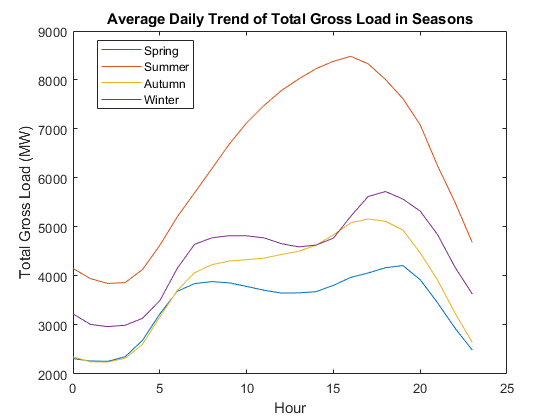

figure;
p_spring = plot(genSpringDaily.Hour, genSpringDaily.mean_sum_GrossLoadMW);
hold on;
p_summer = plot(genSummerDaily.Hour, genSummerDaily.mean_sum_GrossLoadMW);
p_autumn = plot(genAutumnDaily.Hour, genAutumnDaily.mean_sum_GrossLoadMW);
p_winter = plot(genWinterDaily.Hour, genWinterDaily.mean_sum_GrossLoadMW);
legend([p_spring, p_summer, p_autumn, p_winter], ["Spring", "Summer", "Autumn", "Winter"], 'Location', "best");
xlabel("Hour");
ylabel("Total Gross Load (MW)");
title("Average Daily Trend of Total Gross Load in Seasons");
box on;
hold off;

## Daily average power generation of each NYAM units in each season

### Subset by NYAM Units and seasons

genUnitSeasonDaily = zeros(8,24,4);
for i=1:4
    for j=1:8
        genAllSeason = genAllSeasons{i};
        genUnitSeason = genAllSeason(genAllSeason.NYAMUnit == NYAMUnitNames(j), :);
        genUnitSumSeason = groupsummary(genUnitSeason, ["Date","Hour"], "sum", "GrossLoadMW");
        genUnitAveSeason = groupsummary(genUnitSumSeason, "Hour", "mean", "sum_GrossLoadMW");
        genUnitSeasonDaily(j,:,i) = genUnitAveSeason.mean_sum_GrossLoadMW;
    end
end

### Plot daily trend in different seasons

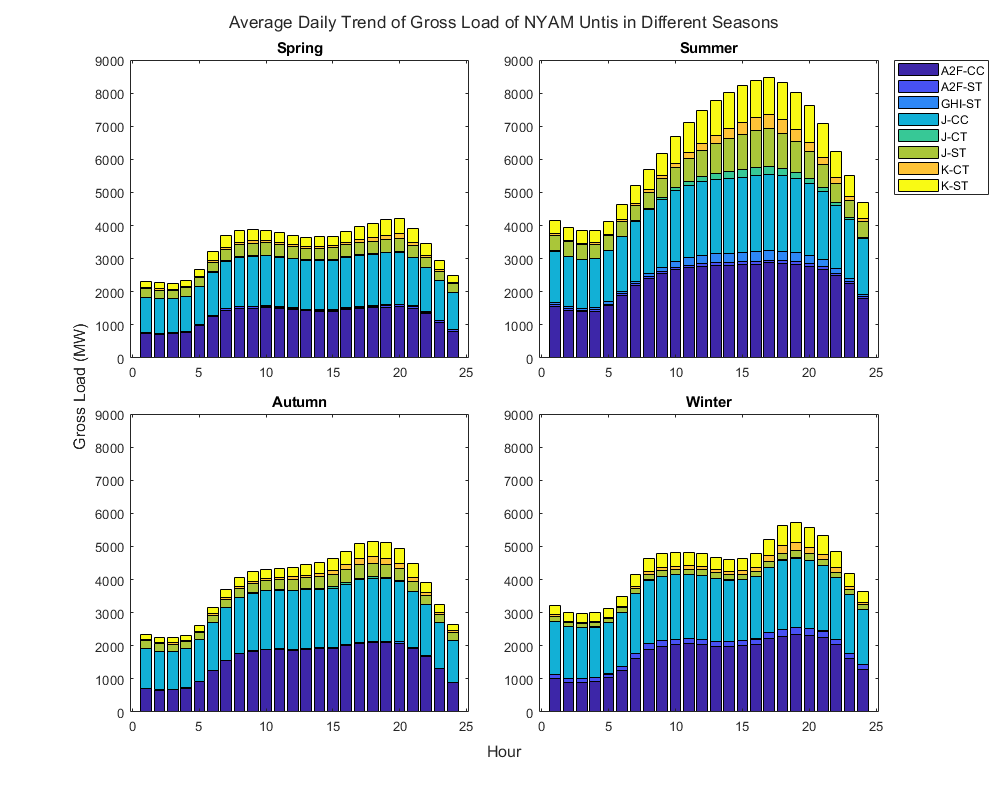

Hour = 1:24;
seasons = ['Spring'; 'Summer'; 'Autumn'; 'Winter'];
t = tiledlayout(2,2,"TileSpacing","compact");
for i=1:4
    nexttile;
    b = bar(Hour, genUnitSeasonDaily(:,:,i),'stacked','FaceColor',"flat");
    for k=1:8
        b(k).CData = k;
    end
    title(seasons(i,:));
    ylim([0, 9000]);
    if i==2
        lgd = legend('A2F-CC', 'A2F-ST', 'GHI-ST', 'J-CC', 'J-CT', 'J-ST', 'K-CT', 'K-ST', 'Location', 'bestoutside');
        set(lgd, "Location", "bestoutside");
    end
end
title(t, "Average Daily Trend of Gross Load of NYAM Untis in Different Seasons");
xlabel(t, "Hour");
ylabel(t, "Gross Load (MW)");
set(gcf, 'Position', [50, 50, 1000, 800]);

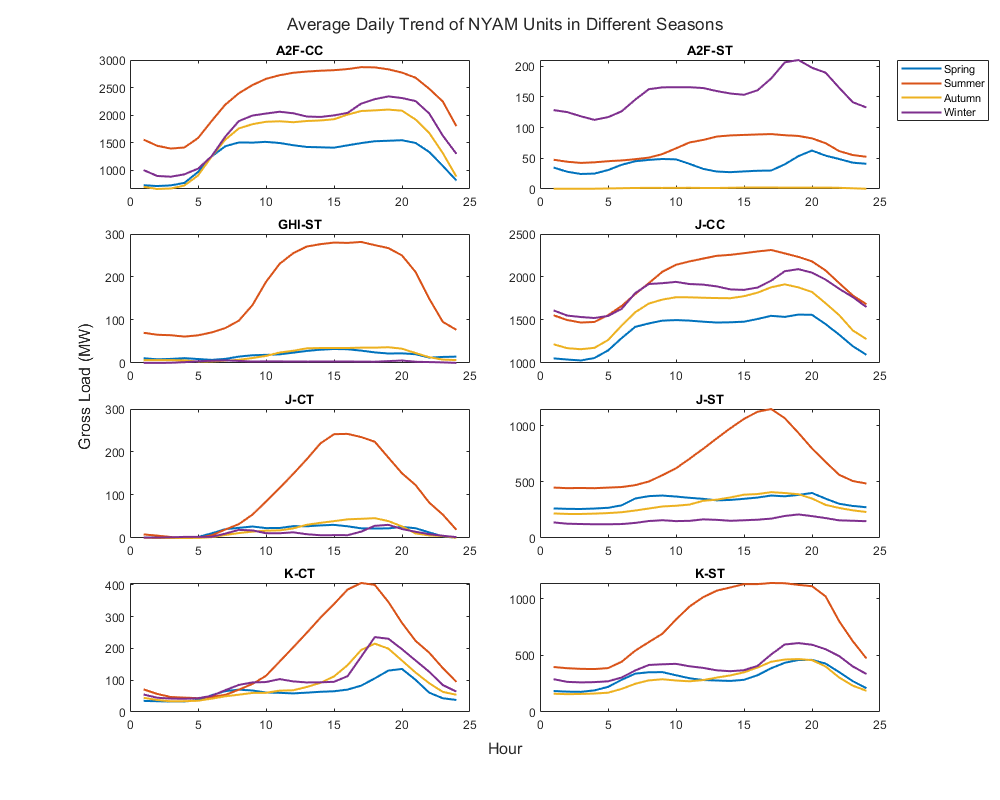

t = tiledlayout(4,2,"TileSpacing","compact");
for i=1:8
    nexttile;
    p1=plot(Hour, genUnitSeasonDaily(i,:,1), 'LineWidth',1.5);
    hold on;
    p2=plot(Hour, genUnitSeasonDaily(i,:,2), 'LineWidth',1.5);
    p3=plot(Hour, genUnitSeasonDaily(i,:,3), 'LineWidth',1.5);
    p4=plot(Hour, genUnitSeasonDaily(i,:,4), 'LineWidth',1.5);
    hold off;
    title(NYAMUnitNames(i));
    if i==2
        lgd = legend([p1,p2,p3,p4],seasons);
        set(lgd, "Location", "bestoutside");
    end
end
title(t, "Average Daily Trend of NYAM Units in Different Seasons");
xlabel(t, "Hour");
ylabel(t, "Gross Load (MW)");

set(gcf, 'Position', [50, 50, 1000, 800]);

genHourlyUnits = table2array(genHourlyAll(:,3:end));
maxGenUnits = zeros(8,1);
minGenUnits = zeros(8,1);
for i=1:8
    data = genHourlyUnits(:,i);
    idx = data > 0;
    data = data(idx);
    maxGen = max(data);
    minGen = min(data);
    maxGenUnits(i) = maxGen;
    minGenUnits(i) = minGen;
end
maxGenUnits

maxGenUnits =         4161
        1633
        1189
        2716
         882
        3729
        1039
        2060


minGenUnits

minGenUnits =    108
     1
     1
   493
     1
     1
     1
    34


maxGenUnitsAve = zeros(8,4);
minGenUnitsAve = zeros(8,4);
for i=1:8
    for j=1:4
        data = genUnitSeasonDaily(i,:,j);
        idx = data > 0;
        data = data(idx);
        maxGen = max(data);
        minGen = min(data);
        maxGenUnitsAve(i,j) = maxGen;
        minGenUnitsAve(i,j) = minGen;
    end
end
maxGenUnitsAve

maxGenUnitsAve =        1545.1       2870.2         2101       2340.3
       62.598       89.424       2.3516       209.94
       32.598       281.51       36.648       6.0444
       1562.7       2314.1       1914.2       2091.2
       30.576       242.09       46.088       30.589
       401.66       1150.6       408.91        210.1
       135.53       406.15       215.18       235.81
        459.4       1137.2        466.6       607.37


minGenUnitsAve

minGenUnitsAve =           714       1394.3       660.65       883.59
       24.446         42.5      0.40659        112.5
       7.2391       61.413       3.2747      0.15556
       1029.5       1470.6       1160.1       1523.4
      0.18478       0.6087     0.043956      0.78889
        258.7       444.18       214.33        122.4
       33.033       43.674       33.637       41.611
       177.86       378.61        157.3        260.9
